## **ASSIGNMENT 2 -- DECODING NEURAL ACTIVITY**

Federico Stella (f.stella@donders.ru.nl)

In this notebook we will take a look at some tecniques aimed at "reading" neural activity and allowing us to interpret its content and to evaluate how much information it carries about a specific set of stimuli, conditions or states. 

This LiveScript MATLAB environemt is very similar to the Jupyter notebook you used in the previous assignment. Differently from Python, we do not need to prepare any environment, you can run the code in this script straight away from any Matlab application. 

You can complete the assignements directly in this notebook or copy any part of the code in anotheratlab LiveScript, another regular script or run it directly from the Command Window. Using a LiveScript like this allows you to insert text, comments or observations, you just need to use the "Text" and "Code" commands at the top to switch between the two modes. 

## **DECODING ON A LINEAR TRACK**

The main aim of this assignment is to familiarize you with the concept of decoding of neural activty. The idea is that if certain neurons are consistently active whenever a stimulus is present, then by oberving at a later time the same neural activity, we can predict the presence of that stimulus, or more generrally argue that the network is currently expressing the neural representation of that stimulus. For more details about decoding you can read this 

In the context of the hippocampus and of place cells, the different positions that an animal can occupy in an environment provide the set of external stimuli that is represented in the activity of the cells. Therefore in the following we will see how recording activity from a set of place cells allows us to reconstruct the current position of the animal with some degree of accuracy. 

**Simulated Place Cells** 

We first generate a place field map to provide a neural representation of the linear environment, much like you have already seen in the previous assignment.  We simulate spike trains as inhomogeneous Poisson processes, with a rate determined by the current animal position. An inhomogeneous Poisson process is a random process where the instantaneous probability to have an event at time  (more precisely, the probability of having an event between times t and t+dt  is given by: 


$$P(event in[t, t+dt]=\lambda(t)dt$$


#### Place Field Properties

track_length = 200; % the length of our linear track (eg in centimeter) 
average_firing_rate = 5; % the peak firing rate, averaged across the population 
n_cells = 10; % how many cells we are recording 
pf_centers = rand(n_cells,1) * track_length; % the centers of the place fields for all cells drawn randomly with a uniform distribution on the track 
pf_size = gamrnd(10,1, n_cells,1); % the size (width) of the place fields, drawn randomly from a gamma distribution 
pf_rate = exprnd(average_firing_rate,n_cells,1); % the peak firing rate for each cell, drawn from an exponential distribution 

#### Build the place field representation 

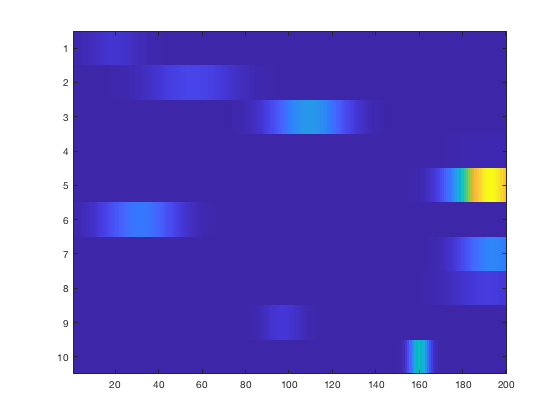

bins=1:track_length; 
true_firing_rate=zeros(n_cells,track_length); 
%Place Fields have a Gaussian shape 
for i=1:n_cells 
    true_firing_rate(i,:)=pf_rate(i).*exp(-(bins-pf_centers(i)).^2/(2*pf_size(i)^2)); 
end 

imagesc(true_firing_rate) 

#### Generate a random trajectory on the track 

Let's simulate the trajectory of the virtual mouse on the track. As we are only interested in the periods during which the animal is moving, we will omit the pauses at tehe two ends of the track. The trajectory will therefore consits of laps directly alternating between the two running directions. 

n_runs = 20; 
av_running_speed = 10;% the average running speed (in cm/s)
fps = 10; % the number of "video frames" per second 
running_speed_a = chi2rnd(av_running_speed, n_runs,1); % running speed in the two directions
running_speed_b = chi2rnd(av_running_speed, n_runs,1); 

x = [];
for i=1:n_runs
run_length = numel(bins) * fps / running_speed_a(i);
run1 = linspace(0.1, numel(bins), round(run_length));
run_length = numel(bins) * fps / running_speed_b(i);
run2 = linspace(numel(bins), 0.1, round(run_length));
x=cat(1,x,run1(:),run2(:));
end
t=(1:numel(x))./fps;  


#### Generate spikes for cells

Combining the rate maps and the trajectory generated above we can now simulate the spiking activity of our neural population.

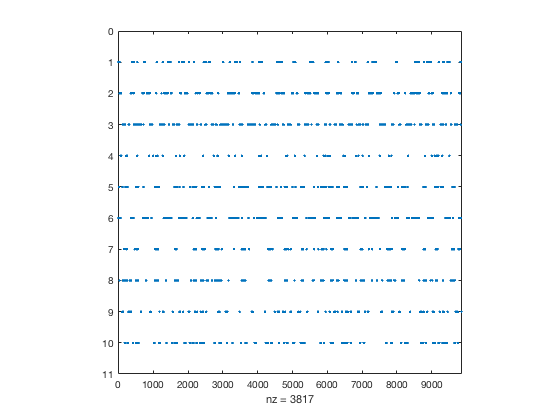

sampling_rate = 10;%This corresponds to time windows of 100ms, a natural choice in the case of hippocampal data. 
t_sampling = (1:numel(t))./sampling_rate;
x_sampling = ceil(interp1(t, x,t_sampling,'linear','extrap'))';
noise_firing_rate = 0.1; % the baseline noise firing rate

spikes = zeros(n_cells,numel(t_sampling));

for i=1:n_cells
    inst_rate = true_firing_rate(i,x_sampling) + randn(1,numel(x_sampling))*noise_firing_rate;
    inst_rate(inst_rate<0) = 0;
    spikes_loc = poissrnd(inst_rate/sampling_rate);
    spikes(i,:)=spikes_loc;
    
end

spy(spikes)
axis square

#### Reconstruct place-related activity from sampled activity

We are now ready to proceed with the first step towards decoding of position. We will start by looking at how different locations are encoded by the neurons. To do that we will collect all the activity emitted by the neurons in a specific location and average it to obtain a Population Vector (PV) associated to that position, or equivalently we will say that the firing rate combination of this PV represent that location. Since we will do this for every location in the environment we will end up having the PVs associated to every portion of the environment. 

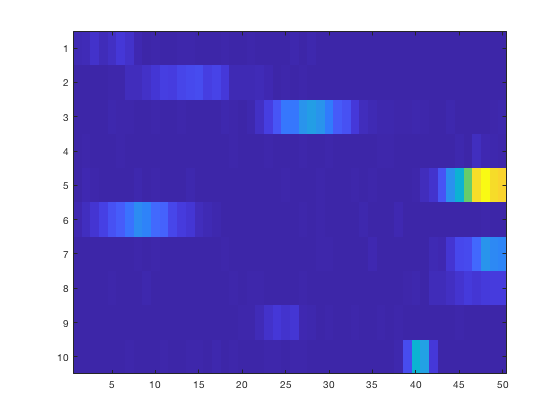

% To estimate the PVs we will use bins of some cms in length 
bin_size=4; % Size in cm of bins to use for encoding
n_bins = track_length/bin_size;

estim_firing_rate=zeros(n_cells,n_bins);

% Rescale the trajectory to the new binning 
x_sampling_binned = ceil(x_sampling/(track_length/n_bins));

% Calculate the PV for every bin
for j=1:n_bins
    
    X_bin=find(x_sampling_binned==j);
    estim_firing_rate(:,j)=sum(spikes(:,X_bin),2)*sampling_rate./(numel(X_bin));
    
    
end

imagesc(estim_firing_rate)

imagesc(true_firing_rate)

Since the spikes we are using to estimate the track representation are a finite sample of the '"ground-truth" maps, and moreover we have added random noise in the process, the reconstructed maps will not be identical to the original ones. Actually, they can be quite different, especially in real experiments where the amount of data is limited, the behaviour of the animal is not completely controlled, neural activity is subject to high level of noise, and obviously we don't have access to the "ground-truth". 

**Question 1: **In the context of the simulated data, one can look at the effects of data amount and level of noise on the accuracy of the PV estimation. Build a table expressing the relationship between noise level, amount of recorded runs and the difference between the real and the reconstructed maps.  

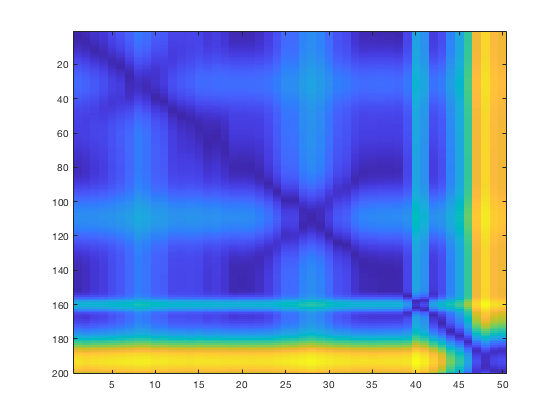

% We can evaluate the difference using euclidean distance, for example 
DD=pdist2(true_firing_rate',estim_firing_rate','euclidean');
imagesc(DD)

Estim_Accuracy = min(DD,[],1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%% mean(Estim_Accuracy) Table %%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% pf_size(alpha)-> %%%     5     %%%%%%%%     10     %%%%%%%%     25     %%%%%%%%     50     %%%%%%%% 
%%%%%%%%%%%%%%%%%%%%%%%
%     n_cells
%        |
%        v
%%%%%%%%%%%%%%%%%%%%%%%
%       10                0.2253 %%%%%%%%    0.4561   %%%%%%%%%   0.6544  %%%%%%%%%  0.9960   %%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%
%       50                0.8755 %%%%%%%%    1.1451   %%%%%%%%%   1.8445  %%%%%%%%%  1.2494   %%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%
%       100               1.4871 %%%%%%%%    1.7244   %%%%%%%%%   2.3205  %%%%%%%%%  3.8487   %%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%
%       1000              12.1208 %%%%%%%%   32.5602   %%%%%%%%%  48.0988  %%%%%%%%%  55.6404  %%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% What becomes clear is that the average accuracy becomes less when there
% are more cells we are recording and when there is more noise. 




**BAYESIAN DECODING**

Now that we have estimated the PVs associated to the track environment, we can move on to decoding. 

A very common approach is given by the so called Bayesian Decoding ([Quiroga](https://www.nature.com/articles/nrn2578) and [Pouget](https://www.nature.com/articles/35039062) for a review on the topic). Let *P(s)* denote the probability of presentation of stimulus *s* (belonging to a set *S*) and *P (r|s)* denote the conditional probability of obtaining a population response *r* (out of a response set *R*) when stimulus *s* is presented. Using Bayes' theorem, we obtain:


$$P(s|r)=\frac{P(r|s)*P(s)}{P(r)}$$


This equation gives the posterior probability that, given a response *r*, stimulus *s* was presented. Bayesian decoding calculates from this posterior probability distribution a single prediction of the most likely stimulus 


$$s^*=argmax_s(P(s|r))$$


In our case the set of stimuli *S *are the different locations in the environment. Since we are looking for the maximum, we can ignore the denominator term P(r), as it is common to all positions *s *(luckily for us, as it is generally very difficult to estimate experimentally)*. *Moreover we will assume that every position s is equiprobable, so we can also ignore the term P(s). Assuming that our neurons are independant (a banality in our simulations, but not necessarily true when considering real neurons), we are left with: 


$$s^*= argmax_s(\prod_iP(r_i|s))$$


And here is the code to perform bayesian decoding: 

x_decoded=zeros(size(spikes,2),1);
for t_bin=1:size(spikes,2)
    
    if(sum(spikes(:,t_bin),1)>0) % Check if the time window contains spikes
    
    Post_p=NaN(size(estim_firing_rate,2),1);
    for i=1:size(estim_firing_rate,2)
        % Note that we work with log so that we can sum probabilities
        % instead of multiplying them 
        Post_p(i)=sum(log(poisspdf(spikes(:,t_bin),estim_firing_rate(:,i)/sampling_rate)));       
    end

    x_decoded(t_bin) = find(Post_p==nanmax(Post_p),1,'first');
    else
    x_decoded(t_bin) = NaN;   
    end
end



**Question 2: **What is the reason for calculating a log-probability instead a probability? 

Calculating the log of probability gives the same maximum, since the log(x) function is increasing if x is. The advantage is that the numbers are not in a big range, but are closer together. For example 0.0000001*0.000000025 is approx 0 for Matlab, while the log of the functions is much easier computed and does not give 0. Also for big numbers you don't get overflow. 

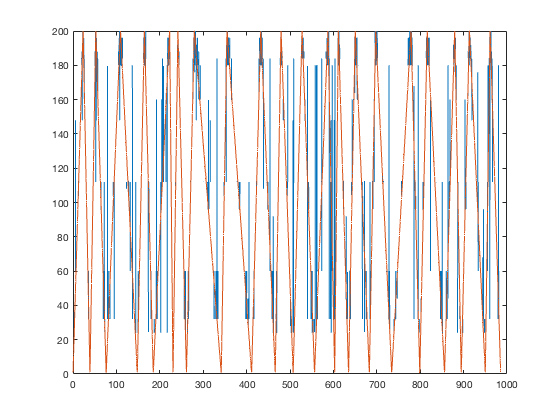

%Plot the real trajectory against the reconstructed one
plot(t_sampling,x_decoded*bin_size,t_sampling,x_sampling)

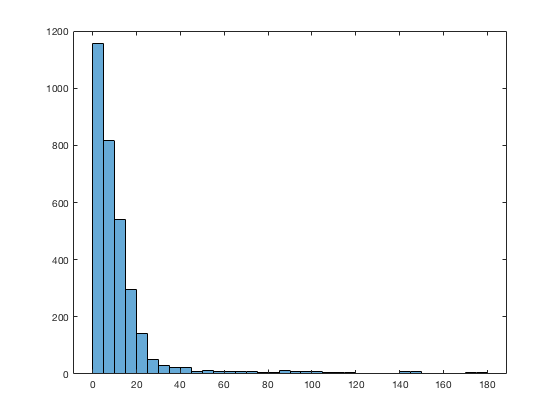

%Distribution of errors
histogram(sqrt(((x_sampling-x_decoded*bin_size).^2)))


%To reduce the effects of the few large errors, the median error, rather
%than the mean error, is a commonly used measure of decoding precision
nanmedian(sqrt(((x_sampling-x_decoded*bin_size).^2)))

ans = 7

**Question 3: **how much data is required to reduce the median error? Use smaller fractions of data to estimate PVs and measure how this affects the decoding error.    

The higher the amount of runs (take 50 for example), the lower the median. Because there is more data. 

**Question 4: **how does the reconstruction error scales with the number of available place cells? Having many cells representing an environment allows for more information to be found in the same time window and reduces the effect of random noise. But how many place cells would be requied on average to accurately represent position on a linear track? Quantify the average decoding error obtainable with different population sizes and find for what value it reaches its asymptot. 

n_cells=10   --->   error=7

n_cells=20   --->   error=7

n_cells=30   --->   error=6

n_cells=50   --->   error=4

n_cells=100 --->   error=3

**Question 5: **Bayesian decoding is not the only available option ([Abbott](https://www.cambridge.org/core/journals/quarterly-reviews-of-biophysics/article/decoding-neuronal-firing-and-modelling-neural-networks/B6387621EFFDFCF5ADE95C965A31D919)). Another possibility is to directly compare the activity present in a given time window with all PVs and find which one is the more "similar" (then the associated position would be the decoded one). As a definition of similarity one can use euclidean distance, correlation, cosine distance. Compare the performance of different decoding approaches. For example use Bayesian and correlation-based decoding.

x_decoded=zeros(size(spikes,2),1);
for t_bin=1:size(spikes,2)
    
    if(sum(spikes(:,t_bin),1)>0) % Check if the time window contains spikes
    
    Post_p=NaN(size(estim_firing_rate,2),1);
    for i=1:size(estim_firing_rate,2)
        % Note that we work with log so that we can sum probabilities
        % instead of multiplying them 
        non_zero = estim_firing_rate(:,i)~=0;
        if sum(non_zero)>0 && sum(spikes(non_zero,t_bin))>0
        Post_p(i) = pdist2(estim_firing_rate(non_zero,i)',spikes(non_zero,t_bin)',['cosine']); 
        end
    end

    x_decoded(t_bin) = find(Post_p==nanmax(Post_p),1,'first');
    else
    x_decoded(t_bin) = NaN;   
    end
end

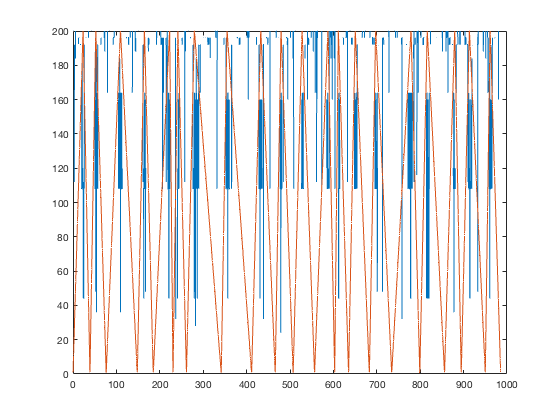

%Plot the real trajectory against the reconstructed one
plot(t_sampling,x_decoded*bin_size,t_sampling,x_sampling)

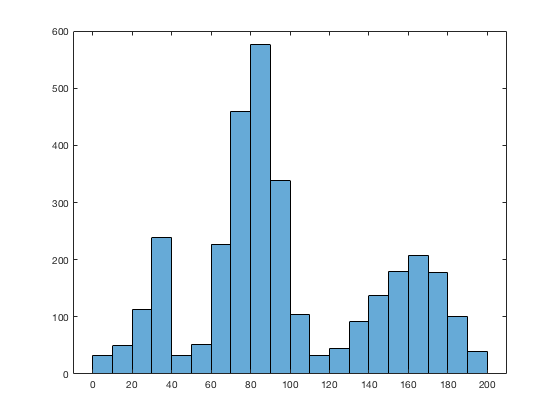

%Distribution of errors
histogram(sqrt(((x_sampling-x_decoded*bin_size).^2)))


%To reduce the effects of the few large errors, the median error, rather
%than the mean error, is a commonly used measure of decoding precision
nanmedian(sqrt(((x_sampling-x_decoded*bin_size).^2)))

ans = 87

#### Multiple place field case

The case presented above is the most ideal one can think of for performing decoding of position: a simple 1D environment with place cells being active in only one location.

We now want to see what are the effects on decoding of more heterogeneous conditions. We start with allowing each place cell to develop, with a certain probability, a second place field in a new location. We can generate such map with the following code:

track_length = 200; % the length of our linear track (eg in centimeter)
average_firing_rate = 5; % the peak firing rate, averaged across the population 
n_cells = 50; % how many cells we are recording
pf_centers = rand(n_cells,2) * track_length; % the centers of the place fields for all cells drawn randomly with a uniform distribution on the track
pf_size = gamrnd(10,1, n_cells,2); % the size (width) of the place fields, drawn randomly from a gamma distribution 
pf_rate = exprnd(average_firing_rate,n_cells,2); % the peak firing rate for each cell, drawn from an exponential distribution


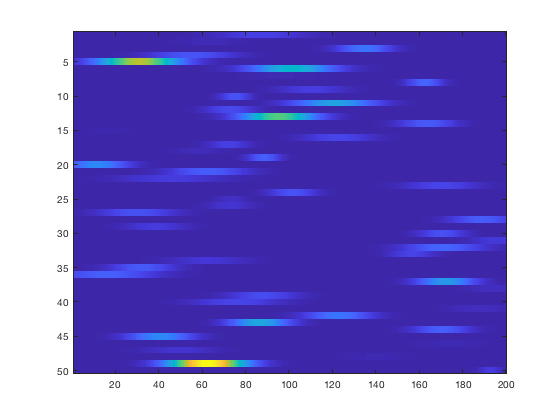

prob_2field=0.01; %This is the probability that a cell will have 2 fields instead of one

bins=1:track_length;
true_firing_rate=zeros(n_cells,track_length);

for i=1:n_cells
    n_fields=1+(rand(1)<prob_2field);
    for j=1:n_fields
    true_firing_rate(i,:)=true_firing_rate(i,:)+pf_rate(i,j).*exp(-(bins-pf_centers(i,j)).^2/(2*pf_size(i,j)^2));
    end
end

imagesc(true_firing_rate)

**Question 6: **Compare the performance of position reconstruction with different values of *prob_2field. *Why is the presence of additional fields making decoding more challenging? 

Because you cannot find the mean of the field. There are two that you need to find. Something like mean(fields) is not possible anymore. 

**Question 7: **Is Bayesian decoding more or less affected than similarity-based methods? 

Bayesian decoding is more affected, because it uses poisspdf function which only has one peak. 

**2D ENVIRONMENT**

Similarly we can ask what effect has increasing the dimensionality of the environment, by for example using a square box instead of a linear track to simulate the movements of the mouse. You can use the following code to simulate the activity of a group of place cells in a 2D environment.

We start as usual by defining the relevant variables: 

room_size = 100; % the side of our square environment (eg in centimeter)
average_firing_rate = 5; % the peak firing rate, averaged across the population 
n_cells = 100; % how many cells we are recording
pf_centers = [rand(n_cells,1) * room_size rand(n_cells,1) * room_size ]; % the centers of the place fields for all cells drawn randomly with a uniform distribution on the track
pf_size = gamrnd(10,1, n_cells,1); % the size (width) of the place fields, drawn randomly from a gamma distribution 
pf_rate = exprnd(average_firing_rate,n_cells,1); % the peak firing rate for each cell, drawn from an exponential distribution



Let's build place fields in 2D

bins=1:room_size;
true_firing_rate=zeros(room_size*room_size,n_cells);

[bin_Y,bin_X]=meshgrid(bins);

bin_Y=bin_Y(:);
bin_X=bin_X(:);
% Place Fields are two-dimensional symmetric Gaussians 
for i=1:n_cells
    true_firing_rate(:,i)=pf_rate(i).*exp(-((bin_Y-pf_centers(i,2)).^2 ...
        +(bin_X-pf_centers(i,1)).^2)/(2*pf_size(i)^2));
end

true_firing_rate = reshape(true_firing_rate,room_size,room_size,n_cells);

We can use a "slider" (Control, above) to visualize the 2D place field of different cells. 

i=19

i = 19

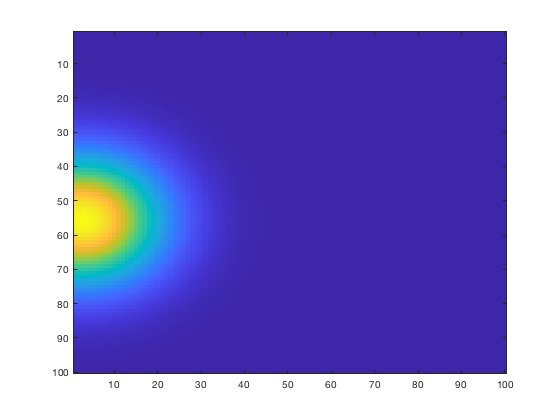

imagesc(true_firing_rate(:,:,i))

Here we build a 2-dimensional trajectory:

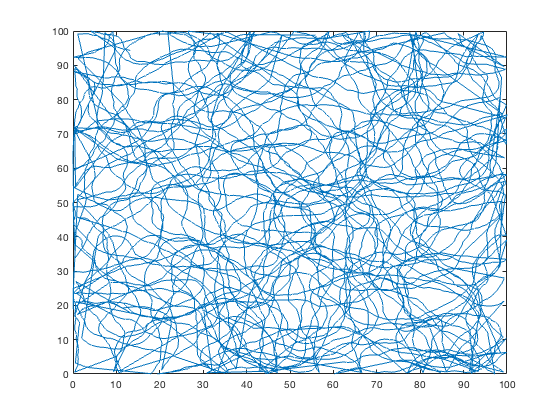

run_length = 1000; % In seconds
av_running_speed = 10;% the average running speed (in cm/s)
fps = 10; % the number of "video frames" per second 
run_bins = run_length*fps;

running_speed = chi2rnd(av_running_speed, run_bins,1); % running speed in the two directions

% Random initial position and direction 
xy_pos = zeros(run_bins,2);
xy_pos(1,:) = [rand(1) rand(1)]*room_size;

direction = rand(1)*2*pi;

for t=2:run_bins
    direction = direction + rand(1)*pi/4 - pi/8; % Direction changes smoothly in time
    xy_pos(t,:) = xy_pos(t-1,:)+running_speed(t)/fps*[cos(direction) sin(direction)];
% Check if the new position is within the box boundaries, otherwise pick anothe one    
while(sum(xy_pos(t,:)>room_size) || sum(xy_pos(t,:)<0))
    direction = rand(1)*2*pi;
    xy_pos(t,:) = xy_pos(t-1,:)+running_speed(t)*[cos(direction) sin(direction)];
end
    

end
t=(1:size(xy_pos,1))./fps;  
plot(xy_pos(:,1),xy_pos(:,2))

And as before we can generate spiking activity along the trajectory.

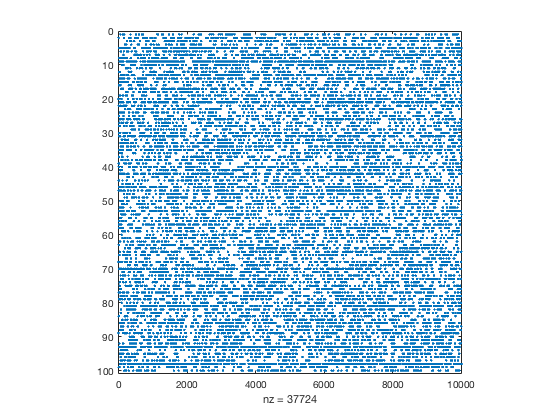

sampling_rate = 10;
t_sampling = (1:numel(t))./sampling_rate;
xy_sampling = zeros(size(xy_pos));
xy_sampling(:,1) = ceil(interp1(t, xy_pos(:,1),t_sampling,'linear','extrap'))';
xy_sampling(:,2) = ceil(interp1(t, xy_pos(:,2),t_sampling,'linear','extrap'))';

noise_firing_rate = 0.1; % the baseline noise firing rate

spikes = zeros(n_cells,numel(t_sampling));

for i=1:n_cells
    for t=1:numel(t_sampling)
    inst_rate = true_firing_rate(xy_sampling(t,2),xy_sampling(t,1),i) + noise_firing_rate;
    spikes_loc = poissrnd(inst_rate/sampling_rate);
    spikes(i,t)=spikes_loc;
    end
end

spy(spikes)
axis square

And finally we can estimate the neural representation from the "recorded" activity, equivalently to what we did before, just with an additional dimension.  

bin_size=10; % Size in cm of bins to use for decoding
n_bins = room_size/bin_size;

estim_firing_rate=zeros(n_bins,n_bins,n_cells);

xy_sampling_binned = ceil(xy_sampling/(bin_size));

for jx=1:n_bins
    for jy=1:n_bins
    XY_bin=find(xy_sampling_binned(:,1)==jx & xy_sampling_binned(:,2)==jy);
    estim_firing_rate(jy,jx,:)=sum(spikes(:,XY_bin),2)*sampling_rate./(numel(XY_bin));
    end     
end



i=9

i = 9

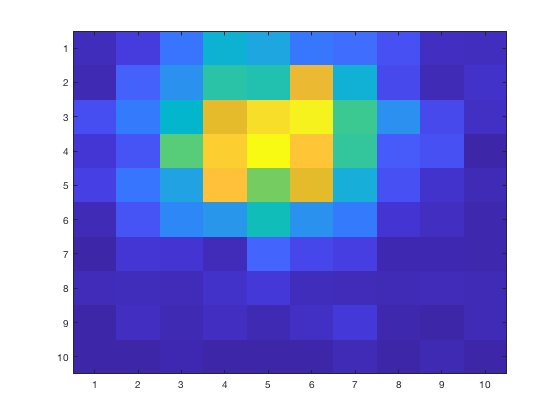

imagesc(estim_firing_rate(:,:,i))

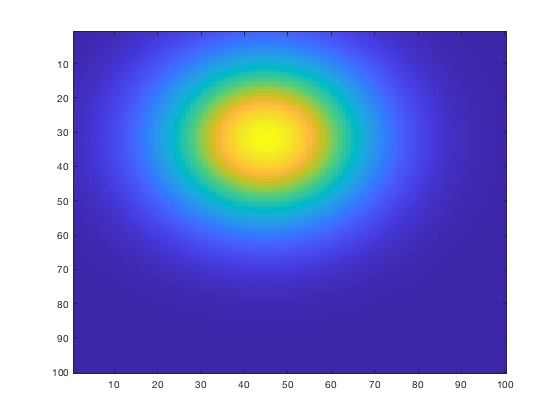

imagesc(true_firing_rate(:,:,i))

**Question 8: **The addition of an extra-dimension has a major effect on the computational complexity of both estimating PVs representing different locations and on the precision with wich one can decode position. Given equivalent amount of noise and place field properties, find how many cells are approximately required to acheive the same decoding precision of the linear track (you can use an arbitrarily long trajectory). 

xy_decoded=zeros(size(spikes,2),2);
estim_firing_rate_reshaped = reshape(estim_firing_rate,n_cells,100)

estim_firing_rate_reshaped =          0         0    0.2326         0    0.2326         0         0         0    0.2326    0.4651         0         0   13.4884         0         0         0         0         0    0.2326         0         0         0    0.2326         0         0         0    0.2326         0    0.2326    0.2326         0    1.1628    0.6977    0.2326         0    0.2326    1.6279    2.0930    0.2326         0         0    0.4651         0    0.4651    0.2326    0.2326    0.2326    0.2326         0         0
    0.5797         0    0.1449         0         0         0         0    0.1449    0.1449    0.1449         0    0.1449    6.8116    0.1449         0    0.1449    0.1449         0    0.1449    0.1449         0         0    0.1449         0    0.1449    0.1449         0    0.1449    0.2899    0.1449         0    0.1449    2.0290         0         0    0.2899    6.9565    3.6232    0.1449         0    0.1449    0.5797         0         0    0.1449         0         0

for t_bin=1:size(spikes,2)
    
    if(sum(spikes(:,t_bin),1)>0) % Check if the time window contains spikes
    
    Post_p=NaN(size(estim_firing_rate_reshaped,2),1);
    for i=1:size(estim_firing_rate_reshaped,2)
        % Note that we work with log so that we can sum probabilities
        % instead of multiplying them 
        Post_p(i)=sum(log(poisspdf(spikes(:,t_bin),estim_firing_rate_reshaped(:,i)/sampling_rate)));       
    end
    xy_decoded(t_bin,:) = find(Post_p==nanmax(Post_p),1,'first');
    else
    xy_decoded(t_bin) = NaN;   
    end
end

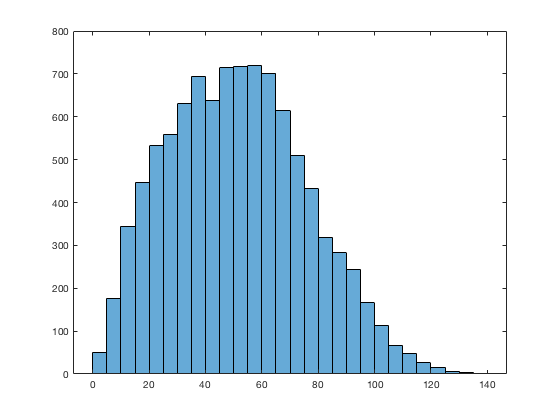

%Distribution of errors
diff = (xy_sampling-xy_decoded);
x_diff = diff(:,1)';
y_diff = diff(:,2)';
distances = sqrt(x_diff.^2+y_diff.^2);
histogram(distances)


%To reduce the effects of the few large errors, the median error, rather
%than the mean error, is a commonly used measure of decoding precision
nanmedian(distances)

ans = 50.4876

We see a broader distribution than for the 1D track. 

**Question 9: **Having the animal thoroughly covering the entire environment is also an issue when in 2-dimensions. Using spatial binning of different size, estimate how long the trajectory should be so that each bin is visited at least twice.  

You can see from the figure that around 2000 the mouse has already visited all places twice for a bin size of 10 cm. The bigger the bin size the less time it takes to visit all places twice, because there are less squares/rectangles to visit.

#### REACTIVATIONS AND REPLAY

The use of decoding methods is not limited to measure the amount of information that a neural population carries about a specific set of stimuli, or to predict what stimulus is present at a given time. It is extremely useful to interpret the content of neural activity when no stimulus is present and such activity is spontaneously generated by the network and is not elicited by a specific stimulus. 

In the case of the hippocampus it has now been extensively observed that during rest periods (either while the animal is standing still, waiting somewhere, or while it is sleeping) place cells reactivate specific patterns of activity corresponding to sequences of locations in the environment. This phenomenon, called "replay" is thought to be critical for the formation of memory, for the acquisition of novel knowledge and for the reorganization of different sorts of information in the brain (You can read [this](https://www.sciencedirect.com/science/article/pii/S0166223610000172?via%3Dihub) for an overview on this vast and ebullient field of research).    

Here we want simulate the occurrence of such reactivation events. Some of them will actually contain sequences, that is, the neural activity will represents a series of locations in the order they appear on the linear track. Other reactivation events will instead contain activity representing locations of the linear track, but these locations will be randomly drawn, so they will present no clear ordering. 

Let's generate these events:   

spikes_react_events = cell(200,1); %200 reactivation events

for event=1:200

sampling_rate = 100;

t_react = 1:100;



noise_x_react=5; % Noise in the reactivation of the sequence
noise_t_react=5; % Noise in the timing of the spikes 

if(event<=100)
    % Generate "real" sequences for the first half of events
    x_start = rand(1)*track_length; % Starting point
    x_end = rand(1)*track_length;% Ending point
    x_react = ceil(linspace(x_start,x_end,100)+randn(1,100)*noise_x_react)';
elseif(event>100)
    % Pick locations randomly for the second half 
    x_react = ceil(rand(100,1)*track_length);
end

x_react(x_react<1)=1;
x_react(x_react>track_length)=track_length;

noise_firing_rate = 0.1; % the baseline noise firing rate

spikes_react = zeros(n_cells,numel(t_react));

% Generate spikes according to the location being reactivated in this event
for i=1:n_cells
    inst_rate = true_firing_rate(i,x_react) + randn(1,numel(x_react))*noise_firing_rate;
    inst_rate(inst_rate<0) = 0;
    spikes_loc = find(poissrnd(inst_rate/sampling_rate));
    spikes_loc = spikes_loc + round(randn(numel(spikes_loc),1)*noise_t_react);
    spikes_loc = spikes_loc(ismember(spikes_loc,1:100));
    spikes_react(i,spikes_loc)=1;
    
end
% Put the data in a cell-array
spikes_react_events{event} = spikes_react;

end


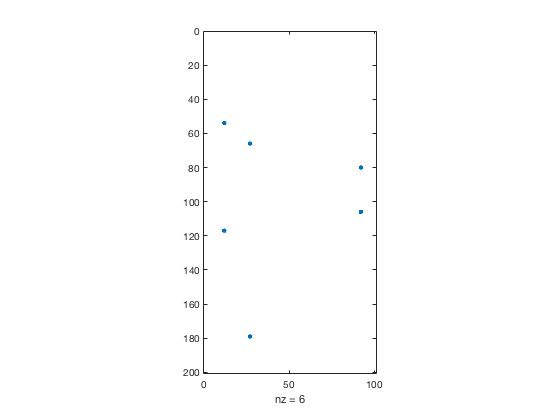

% Reorder cells in terms of the position of their place field on the track 
[~,pf_order]=sort(pf_centers,'ascend');

%We can use this reordering to "visualize the reactivation"
% An example of a sequential reactivation 
Event_Spikes=spikes_react_events{5};
spy(Event_Spikes(pf_order,:))

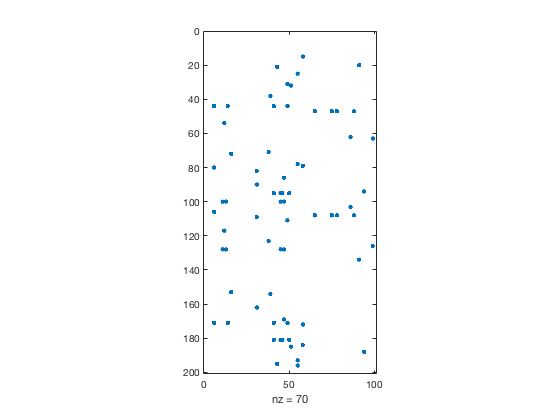


% An example of a non-sequential reactivation
Event_Spikes=spikes_react_events{102};
spy(Event_Spikes(pf_order,:))

We will now decode the activity contained in these events and try to detect sequential activation looking at the correlation between time within the event and decoded position.  

t_resize = 10; % We use spikes from multiple time windows for the decoding

estim_size = size(estim_firing_rate); %reshape, otherwise the code does not work
estim_firing_rate = reshape(estim_firing_rate,estim_size(1)^2,estim_size(3));

reactivation_slope = zeros(200,1);
for event=1:200
    spikes_react = spikes_react_events{event};
    spikes_react_sampled = zeros(n_cells,size(spikes_react,2)/t_resize);

% We generate a new spike matrix with the re-sized window
for t_r=1:100/t_resize
spikes_react_sampled(:,t_r) = sum(spikes_react(:,(t_r-1)*10+1:(t_r)*10),2);
end

%And then we perform the same Bayesian decoding as before 
x_decoded=zeros(size(spikes_react_sampled,2),1);
for t_bin=1:size(spikes_react_sampled,2)
    
    if(sum(spikes_react_sampled(:,t_bin),1)>0) % Check if the time window contains spikes
    
    Post_p=NaN(size(estim_firing_rate,2),1);
    for i=1:size(estim_firing_rate,2)
        
        Post_p(i)=sum(log(poisspdf(spikes_react_sampled(:,t_bin),estim_firing_rate(:,i)/sampling_rate*t_resize)));
       
    end

    x_decoded(t_bin) = find(Post_p==nanmax(Post_p),1,'first');
    else
    x_decoded(t_bin) = NaN;   
    end
end

% Linear fit of 
%beta = polyfit(1:numel(x_decoded),x_decoded',1);
[rr,pp] = corr((1:numel(x_decoded))',x_decoded);

reactivation_slope(event) = pp;%beta(1); --> this is the p-value. If smaller than 0.05 than significant event. 


end



**Question 10: **Can you estimate the amount of times this criterion would label as a sequence a non-sequential event?  

The p-values need to be lower than 0.05. This is the case for the following:

non_seq_events = sum(reactivation_slope<0.05);
disp(non_seq_events);

     7



**Question 11: **Can you think of a better way to define a sequence?

No.